clc;
clear;
close all;

data = readmatrix('dsp_project.csv');

if size(data,2) < 2
    error('Invalid data format');
end

t = data(:,1);
x = data(:,2);

dt = mean(diff(t));
fs = 1/dt;

fprintf('Sampling Frequency (fs): %.2f Hz\n', fs);

Sampling Frequency (fs): 87.93 Hz


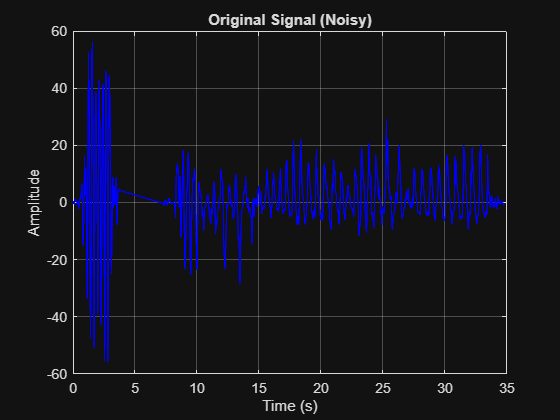


figure;
plot(t, x, 'b');
title('Original Signal (Noisy)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

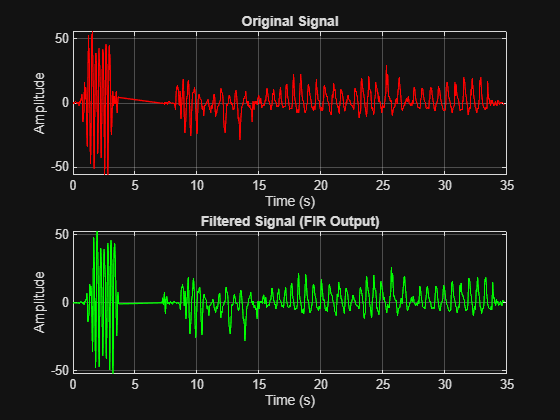


fc = 10;
M = 80;

Wn = fc/(fs/2);

if Wn >= 1
    error('Cutoff frequency must be less than Nyquist frequency');
end

b = fir1(M, Wn, 'low', hamming(M+1));

y = filter(b, 1, x);

figure;

subplot(2,1,1);
plot(t, x, 'r');
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, y, 'g');
title('Filtered Signal (FIR Output)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

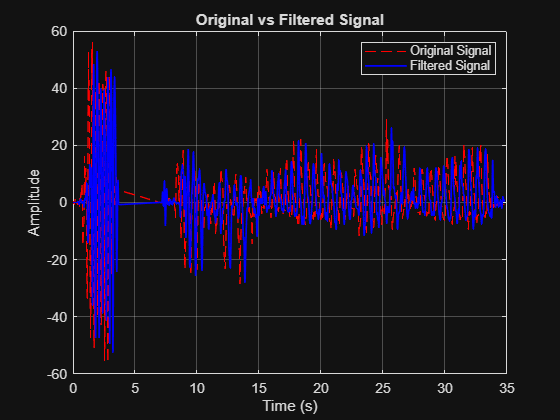


figure;
plot(t, x, 'r--'); hold on;
plot(t, y, 'b', 'LineWidth', 1.2);
title('Original vs Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal', 'Filtered Signal');
grid on;

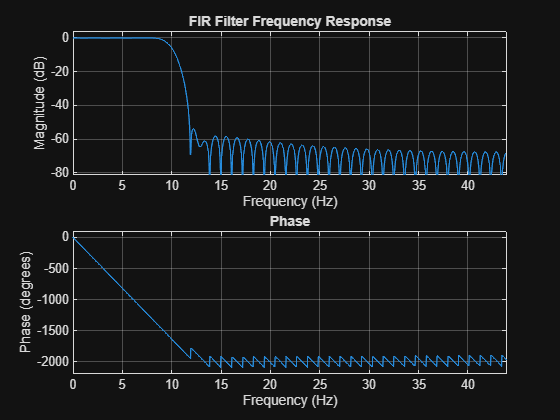


figure;
freqz(b, 1, 1024, fs);
title('FIR Filter Frequency Response');